# M1与S1神经元比较

load('.\loco_20170301_05.mat')

unit_spike = reshape(spikes, 1, []);
w = 0.064; % in second
[firing_rates, valid_units, bin_centers] = calculate_firing_rates(unit_spike, t, w); % instant firing rate
filtered_firing_rates = firing_rates(:, valid_units); % filter out those mean rate < 0.5 Hz
[position, velocity, acceleration, kinematics_time] = calculate_kinematics(finger_pos, t, bin_centers);

区分M1和S1区域神经元

m1_indices = [];
s1_indices = [];

for i = 1:length(valid_units)
    unit_idx = valid_units(i);
    
    % 计算对应的电极索引（每个电极对应5个单元）
    electrode_idx = ceil(unit_idx/5);
    
    if electrode_idx <= length(chan_names)
        channel_name = chan_names{electrode_idx};
        
        % 判断属于哪个脑区
        if contains(upper(channel_name), 'M1')
            m1_indices = [m1_indices, i];
        elseif contains(upper(channel_name), 'S1')
            s1_indices = [s1_indices, i];
        end
    end
end

% 统计各区域神经元数量
fprintf('M1区域有效神经元数量: %d\n', length(m1_indices));

M1区域有效神经元数量: 373


fprintf('S1区域有效神经元数量: %d\n', length(s1_indices));

S1区域有效神经元数量: 134


fprintf('其他/未知区域神经元数量: %d\n', length(valid_units) - length(m1_indices) - length(s1_indices));

其他/未知区域神经元数量: 0


# Linear Decoder

split_ratio = [0.8, 0.2];
split_ratio = split_ratio / sum(split_ratio);

num_samples = size(filtered_firing_rates, 1);
num_train = round(num_samples * split_ratio(1));

idx = 1:num_samples;

train_idx = idx(1:num_train);
test_idx = idx(num_train+1:end);

train_firing_rates = filtered_firing_rates(train_idx, :);
train_position = position(train_idx, :);
train_velocity = velocity(train_idx, :);
train_acceleration = acceleration(train_idx, :);

test_firing_rates = filtered_firing_rates(test_idx, :);
test_position = position(test_idx, :);
test_velocity = velocity(test_idx, :);
test_acceleration = acceleration(test_idx, :);

decoder_p_linear = (train_firing_rates' * train_firing_rates) \ (train_firing_rates' * train_position);
decoder_v_linear = (train_firing_rates' * train_firing_rates) \ (train_firing_rates' * train_velocity);
decoder_a_linear = (train_firing_rates' * train_firing_rates) \ (train_firing_rates' * train_acceleration);

[r2_p, snr_p, predicted_p] = evaluate_decoder_linear(test_firing_rates, test_position, decoder_p_linear);
[r2_v, snr_v, predicted_v] = evaluate_decoder_linear(test_firing_rates, test_velocity, decoder_v_linear);
[r2_a, snr_a, predicted_a] = evaluate_decoder_linear(test_firing_rates, test_acceleration, decoder_a_linear);

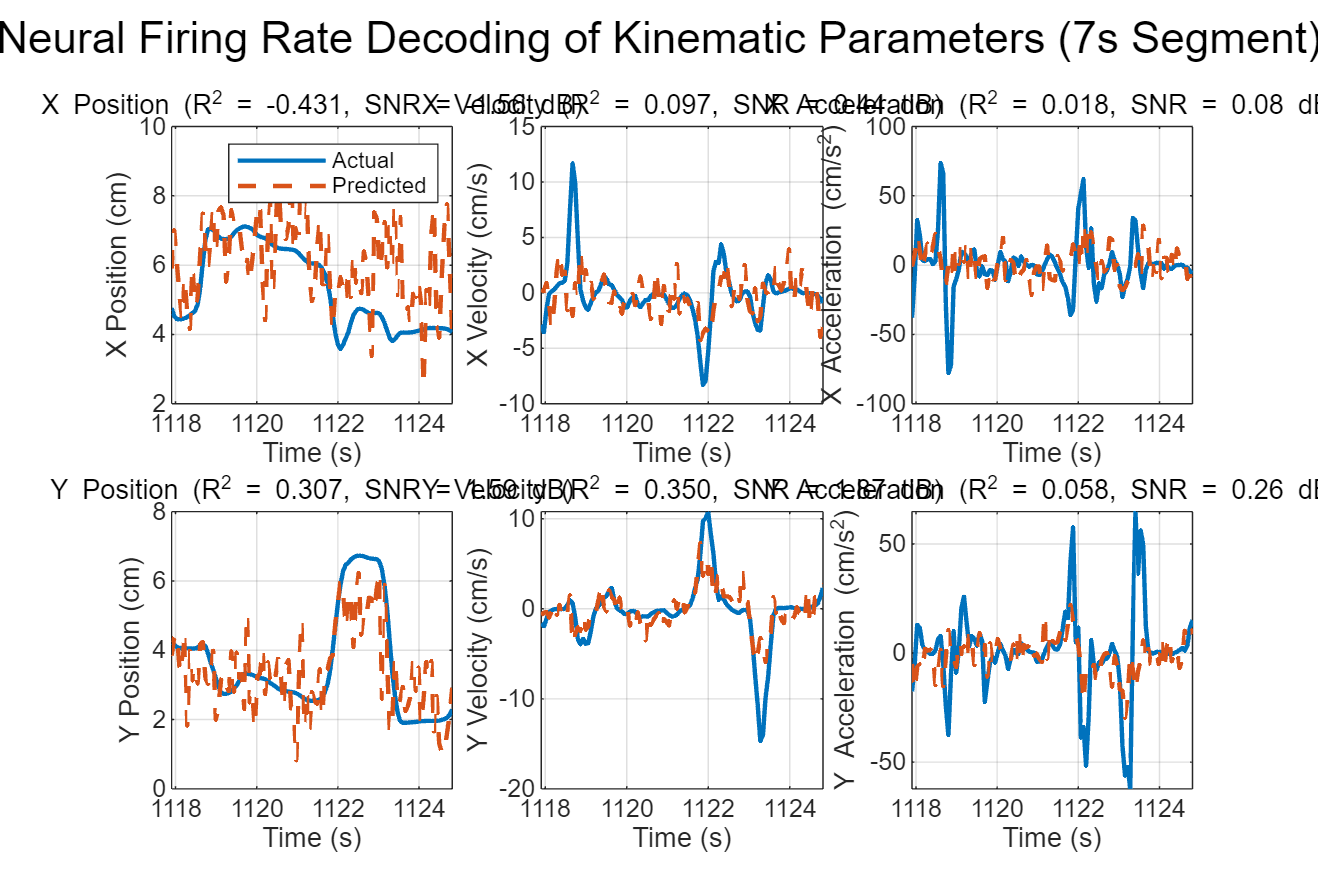

test_time = kinematics_time(test_idx);

% Select middle 7s of the data
total_time_span = test_time(end) - test_time(1);
middle_time = test_time(1) + total_time_span/2;
time_window = 7;
middle_indices = find(test_time >= (middle_time - time_window/2) & test_time <= (middle_time + time_window/2));

% Create a 2×3 subplot arrangement
figure('Position', [100 100 1200 800]);

% Position X
subplot(2,3,1);
plot(test_time(middle_indices), test_position(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual');
hold on;
plot(test_time(middle_indices), predicted_p(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted');
title(sprintf('X Position (R^2 = %.3f, SNR = %.2f dB)', r2_p(1), snr_p(1)));
xlabel('Time (s)');
ylabel('X Position (cm)');
legend('Location', 'northeast');
grid on;

% Velocity X
subplot(2,3,2);
plot(test_time(middle_indices), test_velocity(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual Velocity');
hold on;
plot(test_time(middle_indices), predicted_v(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Velocity');
title(sprintf('X Velocity (R^2 = %.3f, SNR = %.2f dB)', r2_v(1), snr_v(1)));
xlabel('Time (s)');
ylabel('X Velocity (cm/s)');
grid on;

% Acceleration X
subplot(2,3,3);
plot(test_time(middle_indices), test_acceleration(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual Acceleration');
hold on;
plot(test_time(middle_indices), predicted_a(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Acceleration');
title(sprintf('X Acceleration (R^2 = %.3f, SNR = %.2f dB)', r2_a(1), snr_a(1)));
xlabel('Time (s)');
ylabel('X Acceleration (cm/s^2)');
grid on;

% Position Y
subplot(2,3,4);
plot(test_time(middle_indices), test_position(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Position');
hold on;
plot(test_time(middle_indices), predicted_p(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Position');
title(sprintf('Y Position (R^2 = %.3f, SNR = %.2f dB)', r2_p(2), snr_p(2)));
xlabel('Time (s)');
ylabel('Y Position (cm)');
grid on;

% Velocity Y
subplot(2,3,5);
plot(test_time(middle_indices), test_velocity(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Velocity');
hold on;
plot(test_time(middle_indices), predicted_v(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Velocity');
title(sprintf('Y Velocity (R^2 = %.3f, SNR = %.2f dB)', r2_v(2), snr_v(2)));
xlabel('Time (s)');
ylabel('Y Velocity (cm/s)');
grid on;

% Acceleration Y
subplot(2,3,6);
plot(test_time(middle_indices), test_acceleration(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Acceleration');
hold on;
plot(test_time(middle_indices), predicted_a(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Acceleration');
title(sprintf('Y Acceleration (R^2 = %.3f, SNR = %.2f dB)', r2_a(2), snr_a(2)));
xlabel('Time (s)');
ylabel('Y Acceleration (cm/s^2)');
grid on;

% Add overall title
sgtitle('Neural Firing Rate Decoding of Kinematic Parameters (7s Segment)');

# 比较贡献

decoder = decoder_v_linear;

neuron_importance = sqrt(sum(decoder.^2, 2));

% 分离M1和S1区域的神经元贡献
m1_contributions = neuron_importance(m1_indices);
s1_contributions = neuron_importance(s1_indices);

% 计算各区域的总体贡献和平均贡献
m1_total_contribution = sum(m1_contributions);
s1_total_contribution = sum(s1_contributions);
m1_avg_contribution = mean(m1_contributions);
s1_avg_contribution = mean(s1_contributions);

% 计算贡献前20%的阈值
threshold_percentile = 80;
importance_threshold = prctile(neuron_importance, threshold_percentile);

% 统计重要神经元在各区域的分布
m1_important = sum(m1_contributions >= importance_threshold);
s1_important = sum(s1_contributions >= importance_threshold);

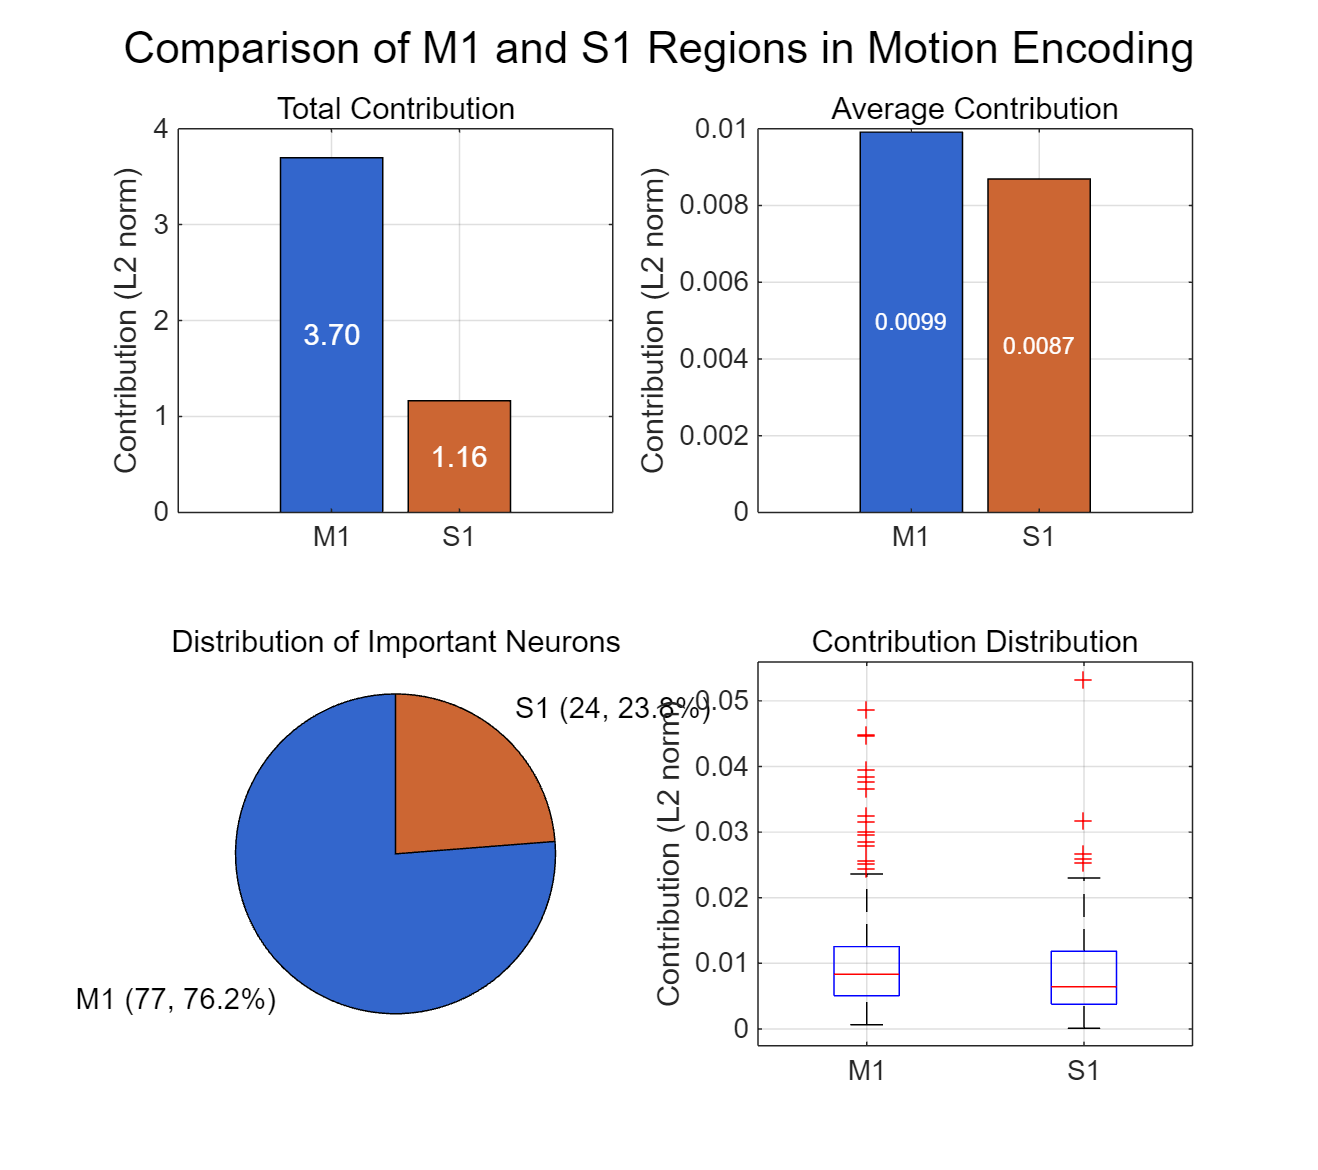

% Create a new figure with appropriate size for 2x2 layout
figure('Position', [100, 100, 900, 800], 'Color', 'white');

% Subplot 1: Total contribution (top-left)
subplot(2, 2, 1);
h1 = bar([m1_total_contribution, s1_total_contribution]);
h1.FaceColor = 'flat';
h1.CData(1,:) = [0.2, 0.4, 0.8]; % M1 color (blue)
h1.CData(2,:) = [0.8, 0.4, 0.2]; % S1 color (orange)
set(gca, 'XTickLabel', {'M1', 'S1'});
title('Total Contribution');
ylabel('Contribution (L2 norm)');
grid on;
box on;
% Add value labels
text(1, m1_total_contribution/2, sprintf('%.2f', m1_total_contribution), ...
     'HorizontalAlignment', 'center', 'Color', 'white');
text(2, s1_total_contribution/2, sprintf('%.2f', s1_total_contribution), ...
     'HorizontalAlignment', 'center', 'Color', 'white');

% Subplot 2: Average contribution (top-right)
subplot(2, 2, 2);
h2 = bar([m1_avg_contribution, s1_avg_contribution]);
h2.FaceColor = 'flat';
h2.CData(1,:) = [0.2, 0.4, 0.8]; % M1 color (blue)
h2.CData(2,:) = [0.8, 0.4, 0.2]; % S1 color (orange)
set(gca, 'XTickLabel', {'M1', 'S1'});
title('Average Contribution');
ylabel('Contribution (L2 norm)');
grid on;
box on;
% Add value labels
text(1, m1_avg_contribution/2, sprintf('%.4f', m1_avg_contribution), ...
     'HorizontalAlignment', 'center', 'Color', 'white', 'FontSize', 8);
text(2, s1_avg_contribution/2, sprintf('%.4f', s1_avg_contribution), ...
     'HorizontalAlignment', 'center', 'Color', 'white', 'FontSize', 8);

% Subplot 3: Important neurons distribution (bottom-left)
subplot(2, 2, 3);
pie_data = [m1_important, s1_important];
colors = [0.2, 0.4, 0.8; 0.8, 0.4, 0.2]; % Blue for M1, Orange for S1
labels = {sprintf('M1 (%d, %.1f%%)', m1_important, 100*m1_important/sum(pie_data)), ...
          sprintf('S1 (%d, %.1f%%)', s1_important, 100*s1_important/sum(pie_data))};
h3 = pie(pie_data, labels);
colormap(colors);
title('Distribution of Important Neurons');

% Subplot 4: Boxplot (bottom-right)
subplot(2, 2, 4);
boxer = [m1_contributions; s1_contributions];
g = [repmat({'M1'},length(m1_contributions),1); repmat({'S1'},length(s1_contributions),1)];
boxplot(boxer, g);
title('Contribution Distribution');
ylabel('Contribution (L2 norm)');
grid on;

% Add overall title
sgtitle('Comparison of M1 and S1 Regions in Motion Encoding');

% 对M1和S1区域神经元分别按贡献度排序
[m1_sorted_importance, m1_sorted_indices] = sort(m1_contributions, 'descend');
[s1_sorted_importance, s1_sorted_indices] = sort(s1_contributions, 'descend');

% 获取实际神经元索引
m1_top_indices = m1_indices(m1_sorted_indices);
s1_top_indices = s1_indices(s1_sorted_indices);

% 获取要绘制的神经元数量(每个区域前10个)
m1_num_to_plot = min(10, length(m1_top_indices));
s1_num_to_plot = min(10, length(s1_top_indices));

% 计算速度方向角度(0-360度)
velocity_angles = atan2d(velocity(:, 2), velocity(:, 1)); % [-180, 180]
velocity_angles(velocity_angles < 0) = velocity_angles(velocity_angles < 0) + 360;

% 将360°分为36个bin，每个bin 10°
angle_bins = 0:10:360;
num_bins = length(angle_bins) - 1;
bin_centers = (angle_bins(1:end-1) + angle_bins(2:end)) / 2;

% 为静止窗口创建掩码(速度接近0的时间点)
speed = sqrt(sum(velocity.^2, 2));
movement_mask = speed > 0.01; % 0.01 cm/s作为运动阈值
valid_samples = find(movement_mask);
valid_angles = velocity_angles(valid_samples);

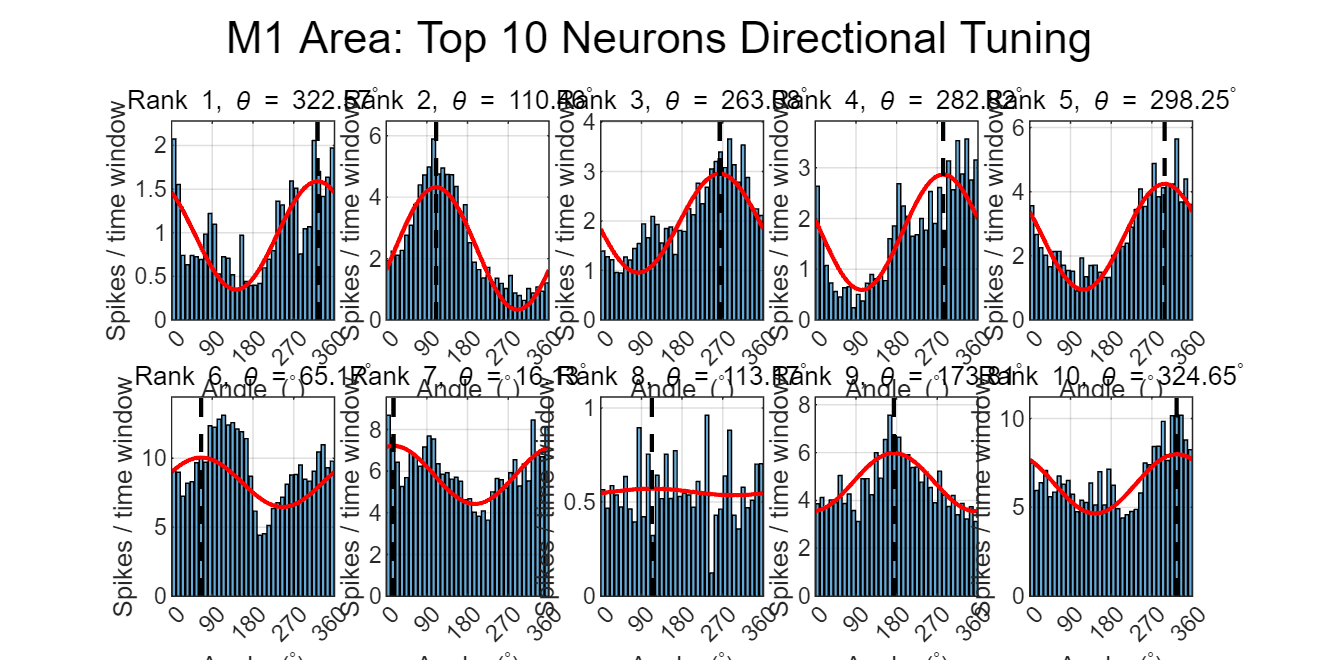

% 绘制M1区域前10个神经元的方向调谐特性
fit_func = @(params, x) params(1) .* cosd(x + params(2)) + params(3);

figure('Position', [100, 100, 1200, 600]);

for i = 1:m1_num_to_plot
    neuron_idx = m1_top_indices(i);
    neuron_firing_rate = filtered_firing_rates(:, neuron_idx);
    valid_rates = neuron_firing_rate(valid_samples);
    
    subplot(2, 5, i);
    
    mean_rates = zeros(num_bins, 1);
    
    for bin = 1:num_bins
        bin_mask = velocity_angles >= angle_bins(bin) & velocity_angles < angle_bins(bin+1) & movement_mask;
        if any(bin_mask)
            mean_rates(bin) = mean(neuron_firing_rate(bin_mask));
        end
    end
    
    h_bar = bar(bin_centers, mean_rates);
    h_bar.FaceAlpha = 0.6; % 透明度
    hold on;

    % 余弦拟合
    initial_params = [1, 0, mean(valid_rates)];
    
    % 尝试多个初始参数，选择最佳拟合
    best_cost = Inf;
    best_params = initial_params;
    
    for phase_start = 0:45:315
        test_params = [1, phase_start, mean(valid_rates)];
        cost_func = @(params) sum((fit_func(params, valid_angles) - valid_rates).^2);
        
        try
            [fitted_params, cost] = fminsearch(cost_func, test_params, optimset('Display', 'off'));
            
            if cost < best_cost
                best_cost = cost;
                best_params = fitted_params;
            end
        catch
            continue;
        end
    end
    
    fitted_params = best_params;

    % 获取拟合参数
    a = fitted_params(1);
    theta = mod(fitted_params(2), 360);
    b = fitted_params(3);

    % 绘制拟合曲线
    x_fit = 0:1:360;
    y_fit = fit_func(fitted_params, x_fit);
    plot(x_fit, y_fit, 'r-', 'LineWidth', 1.5);

    % 计算首选方向
    if a > 0
        pd = mod(360 - theta, 360);
    else
        pd = mod(540 - theta, 360);
    end

    % 设置y轴范围
    y_max = max(mean_rates);
    y_min = min([0; mean_rates]);
    y_range = [y_min, y_max + 0.1*(y_max-y_min)];

    plot([pd, pd], y_range, 'k--', 'LineWidth', 1.5);
    
    title(sprintf('Rank %d, \\theta = %.2f^{\\circ}', i, pd));
    xlabel('Angle (^{\circ})');
    ylabel('Spikes / time window');
    xlim([0, 360]);
    ylim(y_range);
    set(gca, 'XTick', 0:90:360);
    grid on;
    hold off;
end

sgtitle('M1 Area: Top 10 Neurons Directional Tuning');

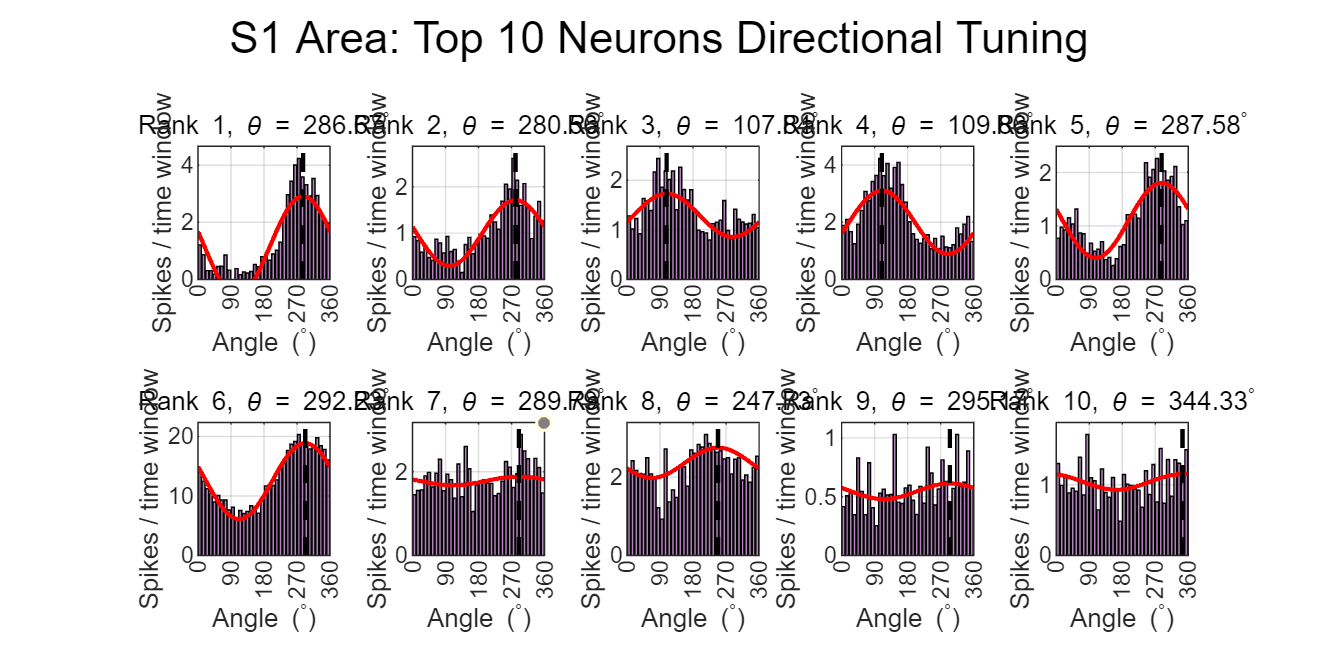

% 绘制S1区域前10个神经元的方向调谐特性
figure('Position', [100, 100, 1200, 600]);

for i = 1:s1_num_to_plot
    neuron_idx = s1_top_indices(i);
    neuron_firing_rate = filtered_firing_rates(:, neuron_idx);
    valid_rates = neuron_firing_rate(valid_samples);
    
    subplot(2, 5, i);
    
    % 计算各方向的平均发放率
    mean_rates = zeros(num_bins, 1);
    
    for bin = 1:num_bins
        bin_mask = velocity_angles >= angle_bins(bin) & velocity_angles < angle_bins(bin+1) & movement_mask;
        if any(bin_mask)
            mean_rates(bin) = mean(neuron_firing_rate(bin_mask));
        end
    end
    
    h_bar = bar(bin_centers, mean_rates);
    h_bar.FaceAlpha = 0.6; % 透明度
    h_bar.FaceColor = '#7E2F8E';
    hold on;

    % 余弦拟合
    initial_params = [1, 0, mean(valid_rates)];
    
    % 尝试多个初始参数，选择最佳拟合
    best_cost = Inf;
    best_params = initial_params;
    
    for phase_start = 0:45:315
        test_params = [1, phase_start, mean(valid_rates)];
        cost_func = @(params) sum((fit_func(params, valid_angles) - valid_rates).^2);
        
        try
            [fitted_params, cost] = fminsearch(cost_func, test_params, optimset('Display', 'off'));
            
            if cost < best_cost
                best_cost = cost;
                best_params = fitted_params;
            end
        catch
            continue;
        end
    end
    
    fitted_params = best_params;

    % 获取拟合参数
    a = fitted_params(1);
    theta = mod(fitted_params(2), 360);
    b = fitted_params(3);

    % 绘制拟合曲线
    x_fit = 0:1:360;
    y_fit = fit_func(fitted_params, x_fit);
    plot(x_fit, y_fit, 'r-', 'LineWidth', 1.5);

    % 计算首选方向
    if a > 0
        pd = mod(360 - theta, 360);
    else
        pd = mod(540 - theta, 360);
    end

    % 设置y轴范围
    y_max = max(mean_rates);
    y_min = min([0; mean_rates]);
    y_range = [y_min, y_max + 0.1*(y_max-y_min)];

    plot([pd, pd], y_range, 'k--', 'LineWidth', 1.5);
    
    title(sprintf('Rank %d, \\theta = %.2f^{\\circ}', i, pd));
    xlabel('Angle (^{\circ})');
    ylabel('Spikes / time window');
    xlim([0, 360]);
    ylim(y_range);
    set(gca, 'XTick', 0:90:360);
    grid on;
    hold off;
end

sgtitle('S1 Area: Top 10 Neurons Directional Tuning');

% 计算M1和S1区域所有重要神经元的偏好方向
m1_important_indices = m1_indices(m1_contributions >= importance_threshold);
s1_important_indices = s1_indices(s1_contributions >= importance_threshold);

% 初始化存储首选方向的数组
m1_pds = zeros(length(m1_important_indices), 1);
s1_pds = zeros(length(s1_important_indices), 1);

% 计算M1区域重要神经元的偏好方向
for i = 1:length(m1_important_indices)
    neuron_idx = m1_important_indices(i);
    neuron_firing_rate = filtered_firing_rates(:, neuron_idx);
    valid_rates = neuron_firing_rate(valid_samples);
    
    % 余弦拟合
    initial_params = [1, 0, mean(valid_rates)];
    
    % 尝试多个初始参数，选择最佳拟合
    best_cost = Inf;
    best_params = initial_params;
    
    for phase_start = 0:45:315
        test_params = [1, phase_start, mean(valid_rates)];
        cost_func = @(params) sum((fit_func(params, valid_angles) - valid_rates).^2);
        
        try
            [fitted_params, cost] = fminsearch(cost_func, test_params, optimset('Display', 'off'));
            
            if cost < best_cost
                best_cost = cost;
                best_params = fitted_params;
            end
        catch
            continue;
        end
    end
    
    fitted_params = best_params;

    % 获取拟合参数
    a = fitted_params(1);
    theta = mod(fitted_params(2), 360);

    % 计算首选方向
    if a > 0
        pd = mod(360 - theta, 360);
    else
        pd = mod(540 - theta, 360);
    end
    
    m1_pds(i) = pd;
end

% 计算S1区域重要神经元的偏好方向
for i = 1:length(s1_important_indices)
    neuron_idx = s1_important_indices(i);
    neuron_firing_rate = filtered_firing_rates(:, neuron_idx);
    valid_rates = neuron_firing_rate(valid_samples);
    
    % 余弦拟合
    initial_params = [1, 0, mean(valid_rates)];
    
    % 尝试多个初始参数，选择最佳拟合
    best_cost = Inf;
    best_params = initial_params;
    
    for phase_start = 0:45:315
        test_params = [1, phase_start, mean(valid_rates)];
        cost_func = @(params) sum((fit_func(params, valid_angles) - valid_rates).^2);
        
        try
            [fitted_params, cost] = fminsearch(cost_func, test_params, optimset('Display', 'off'));
            
            if cost < best_cost
                best_cost = cost;
                best_params = fitted_params;
            end
        catch
            continue;
        end
    end
    
    fitted_params = best_params;

    % 获取拟合参数
    a = fitted_params(1);
    theta = mod(fitted_params(2), 360);

    % 计算首选方向
    if a > 0
        pd = mod(360 - theta, 360);
    else
        pd = mod(540 - theta, 360);
    end
    
    s1_pds(i) = pd;
end

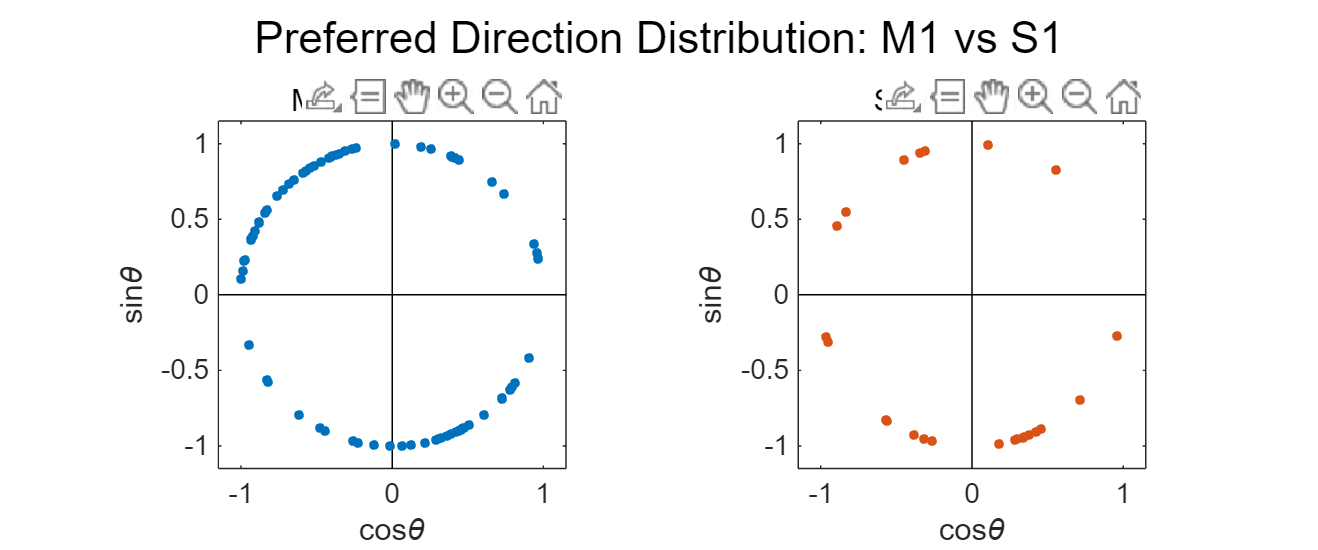

% 将偏好方向转换为笛卡尔坐标
m1_pdx = cosd(m1_pds);
m1_pdy = sind(m1_pds);
s1_pdx = cosd(s1_pds);
s1_pdy = sind(s1_pds);

% 绘制M1区域神经元偏好方向分布
figure('Position', [100, 100, 1200, 500]);

% M1区域
subplot(1, 2, 1);
plot([-1.15 1.15], [0 0], 'k-');
hold on;
plot([0 0], [-1.15 1.15], 'k-');
plot(m1_pdx, m1_pdy, '.', MarkerSize=10, Color='#0072BD');
xlim([-1.15, 1.15]);
ylim([-1.15, 1.15]);
xlabel('cos\theta');
ylabel('sin\theta');
title(sprintf('M1 Area: n=%d', length(m1_pds)));
axis square;

% S1区域
subplot(1, 2, 2);
plot([-1.15 1.15], [0 0], 'k-');
hold on;
plot([0 0], [-1.15 1.15], 'k-');
plot(s1_pdx, s1_pdy, '.', MarkerSize=10, Color='#D95319');
xlim([-1.15, 1.15]);
ylim([-1.15, 1.15]);
xlabel('cos\theta');
ylabel('sin\theta');
title(sprintf('S1 Area: n=%d', length(s1_pds)));
axis square;

sgtitle('Preferred Direction Distribution: M1 vs S1');